# Cinemática

clc;
clear all;

## Cinemática de cuerpo rígido

### Algebra de vectores

En el algebra de vectores siempre se suman las cantidades que se encuentran en la misma dirección de la base (vectores ortogonales)


$${\mathit{\mathbf{r}}}_2 ={\mathit{\mathbf{r}}}_1 +\mathit{\mathbf{d}}$$


donde


$$\begin{array}{l}
{\mathit{\mathbf{r}}}_2 =x_2 \mathbf{i}+y_2 \mathbf{j}+z_2 \mathbf{k}\\
{\mathit{\mathbf{r}}}_1 =x_1 \mathbf{i}+y_1 \mathbf{j}+z_1 \mathbf{k}\\
\mathit{\mathbf{d}}=x_0 \mathbf{i}+y_0 \mathbf{j}+z_0 \mathbf{k}
\end{array}$$


Entonces


$$\left.{\mathit{\mathbf{r}}}_2 =\left(x_1 +x_0 \right)\right)\mathbf{i}+\left(y_1 +y_0 \right)\mathbf{j}+\left(z_1 +z_0 \right)\mathbf{k}$$


Tambien se puede representar en forma matricial


$${\mathit{\mathbf{r}}}_2 =\left\lbrack \begin{array}{c}
x_2 \\
y_2 \\
z_2 
\end{array}\right\rbrack ={\mathit{\mathbf{r}}}_1 +\mathit{\mathbf{d}}=\left\lbrack \begin{array}{c}
x_1 \\
y_1 \\
z_1 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 
\end{array}\right\rbrack$$


r1 = [1, 2.5];
d = [0.8, 0.2];
r2 = r1 + d

r2 =     1.8000    2.7000


Visualmente se observa lo siguiente, se utilza un vector origen $O$

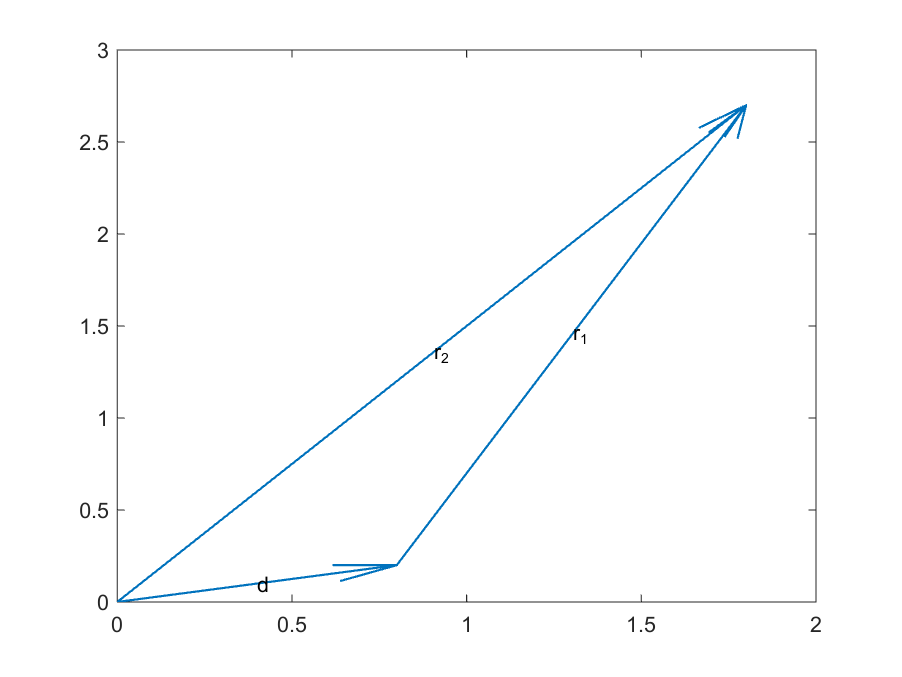

O = [0,0];
% Puntos de origen de los 3 vectores
X = [O(1), d(1), O(1)];
Y = [O(2), d(2), O(2)];
% Extension de los 3 vectores
U = [d(1), r1(1), r2(1)];
V = [d(2), r1(2), r2(2)];
% Dibujo de los vectores, sin escala y grosor de dibujo 1
figure(1);
quiver(X,Y,U,V, 'off','LineWidth', 1)
% Agregar texto para identificar el vector
text(r1(1)/2+d(1), r1(2)/2+d(2), 'r_1')
text(d(1)/2, d(2)/2, 'd')
text(r2(1)/2, r2(2)/2, 'r_2')

### Sistemas de Referencia

Las magnitudes en cada dirección dependen del sistema de referencia en el cual estén definidas

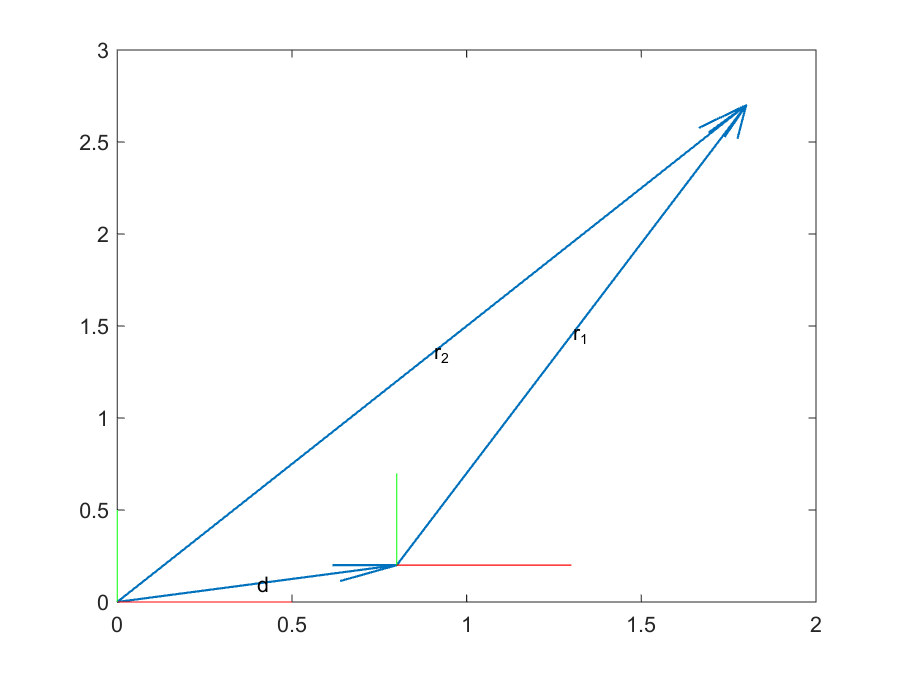

figure(2);
% Dibujo de los vectores, sin escala y grosor de dibujo 1
quiver(X,Y,U,V, 'off','LineWidth', 1)
% Agregar texto para identificar el vector
text(r1(1)/2+d(1), r1(2)/2+d(2), 'r_1')
text(d(1)/2, d(2)/2, 'd')
text(r2(1)/2, r2(2)/2, 'r_2')
% Se mantiene la figura
%Se define una rotacion de 0° respecto al eje Z
axang = [0, 0, 1, 0];      
% Se transforma en un cuaternion
quat0 = axang2quat(axang);          %Cuaternion por sistema de referencia global
quat1 = quat0;                      %Cuaternion por sistema de referencia del cuerpo 1
hold on;            %Se grafica en el mismo gráfico
plotTransforms([0,0,0; d(1), d(2), 0], [quat0; quat1], "FrameSize", 0.5);
hold off;
view(2);

Es posible expresar un vector en distintos sistemas de referencia, un sistema$B\left(\textrm{oxyz}\right)$puede estar acoplado a un cuerpo rígido, el cual se mueve de manera libre en un sistema global de referencia $G\left(\textrm{OXYZ}\right)$.


$${}^G{\mathit{\mathbf{r}}}=$$

$$X\;\mathbf{I}+Y\;\mathbf{J}+Z\;\mathbf{K}={}^B{\mathit{\mathbf{r}}}=x\;\mathbf{i}+y\;\mathbf{j}+z\;\mathbf{k}$$
 

Como mencionaos anteriormente, siempre se suman las cantidades que se encuentran en la misma dirección de los vectores ortogonales, sin embargo, para este caso los vectores ortogonales de ambas bases podrían no tener la misma dirección.


$$\mathbf{I}\cdot \mathbf{i}\not= 1,\;\;\;\;\;\;\;\;\mathbf{I}\cdot \mathbf{j}\not= 0,\;\;\;\;\;\;\;\;\mathbf{I}\cdot \mathbf{k}\not= 0$$


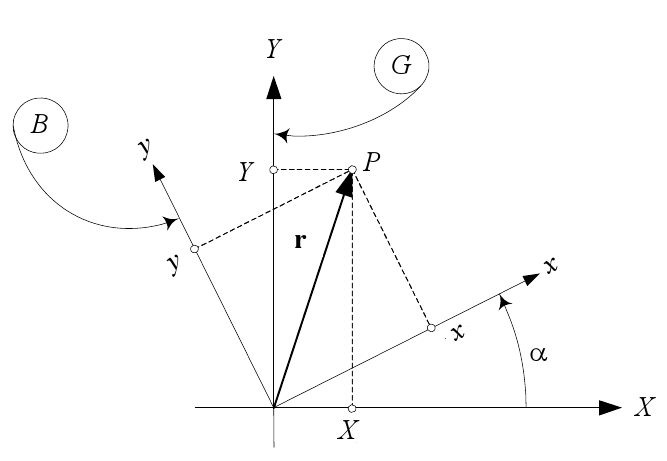

Entonces sí se quisiese expresar cualquier vector de un sistema de referencia a otro, se tiene que encontrar la relación entre las bases


$$\begin{array}{l}
X\;={}^G{\mathit{\mathbf{r}}}\cdot \mathbf{I}={}^B{\mathit{\mathbf{r}}}\cdot \mathbf{I}=x\;\mathbf{i}\cdot \mathbf{I}+y\;\mathbf{j}\cdot \mathbf{I}+z\;\mathbf{k}\cdot \mathbf{I}\\
Y\;={}^G{\mathit{\mathbf{r}}}\cdot \mathbf{J}={}^B{\mathit{\mathbf{r}}}\cdot \mathbf{J}=x\;\mathbf{i}\cdot \mathbf{J}+y\;\mathbf{j}\cdot \mathbf{J}+z\;\mathbf{k}\cdot \mathbf{J}\\
Z\;={}^G{\mathit{\mathbf{r}}}\cdot \mathbf{K}={}^B{\mathit{\mathbf{r}}}\cdot \mathbf{K}=x\;\mathbf{i}\cdot \mathbf{K}+y\;\mathbf{j}\cdot \mathbf{K}+z\;\mathbf{k}\cdot \mathbf{K}
\end{array}$$


Expresado en forma matricial


$$\left\lbrack \begin{array}{c}
X\\
Y\\
Z
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\mathbf{i}\cdot \mathbf{I} & \mathbf{j}\cdot \mathbf{I} & \mathbf{k}\cdot \mathbf{I}\\
\;\mathbf{i}\cdot \mathbf{J} & \;\mathbf{j}\cdot \mathbf{J} & \;\mathbf{k}\cdot \mathbf{J}\\
\;\mathbf{i}\cdot \mathbf{K} & \;\mathbf{j}\cdot \mathbf{K} & \;\mathbf{k}\cdot \mathbf{K}
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$$


### Matriz de rotación

${}^G{\mathit{\mathbf{r}}}$=${}^G{\mathit{\mathbf{R}}}_B$${}^B{\mathit{\mathbf{r}}}$


$${}^G{\mathit{\mathbf{R}}}_B=\left\lbrack \begin{array}{ccc}
\mathbf{i}\cdot \mathbf{I} & \mathbf{j}\cdot \mathbf{I} & \mathbf{k}\cdot \mathbf{I}\\
\;\mathbf{i}\cdot \mathbf{J} & \;\mathbf{j}\cdot \mathbf{J} & \;\mathbf{k}\cdot \mathbf{J}\\
\;\mathbf{i}\cdot \mathbf{K} & \;\mathbf{j}\cdot \mathbf{K} & \;\mathbf{k}\cdot \mathbf{K}
\end{array}\right\rbrack$$


La matriz de rotación nos define una relación entre las bases de los sistemas de referencia. Generalmente estas matrices se definen como giros respecto a uno de los ejes coordenados, de este modo los componentes de la matriz se pueden expresar como funciones transcendentales.

Ejercicio: Determina los componentes de la matriz de rotación respecto a ejes globales


$${}{\mathit{\mathbf{R}}}_{Z,\gamma \;}=$$

$$\left\lbrack \begin{array}{ccc}
\mathbf{i}\cdot \mathbf{I} & \mathbf{j}\cdot \mathbf{I} & 0\\
\;\mathbf{i}\cdot \mathbf{J} & \;\mathbf{j}\cdot \mathbf{J} & \;0\\
\;0 & \;0 & \;1
\end{array}\right\rbrack$$



$${}{\mathit{\mathbf{R}}}_{X,\alpha \;}=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
\;0 & \;\mathbf{j}\cdot \mathbf{J} & \;\mathbf{k}\cdot \mathbf{J}\\
\;0 & \;\mathbf{j}\cdot \mathbf{K} & \;\mathbf{k}\cdot \mathbf{K}
\end{array}\right\rbrack$$



$${}{\mathit{\mathbf{R}}}_{Y,\beta \;}=\left\lbrack \begin{array}{ccc}
\mathbf{i}\cdot \mathbf{I} & 0 & \mathbf{k}\cdot \mathbf{I}\\
\;0 & \;1 & 0\\
\;\mathbf{i}\cdot \mathbf{K} & \;0 & \;\mathbf{k}\cdot \mathbf{K}
\end{array}\right\rbrack$$


Ejercicio: Determina los componentes de la matriz de rotación respecto a ejes globales, con ángulos negativos


$${}{\mathit{\mathbf{R}}}_{Z,-\gamma \;}=$$

$$\left\lbrack \begin{array}{ccc}
\mathbf{i}\cdot \mathbf{I} & \mathbf{j}\cdot \mathbf{I} & 0\\
\;\mathbf{i}\cdot \mathbf{J} & \;\mathbf{j}\cdot \mathbf{J} & \;0\\
\;0 & \;0 & \;1
\end{array}\right\rbrack$$



$${}{\mathit{\mathbf{R}}}_{X,-\alpha \;}=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
\;0 & \;\mathbf{j}\cdot \mathbf{J} & \;\mathbf{k}\cdot \mathbf{J}\\
\;0 & \;\mathbf{j}\cdot \mathbf{K} & \;\mathbf{k}\cdot \mathbf{K}
\end{array}\right\rbrack$$



$${}{\mathit{\mathbf{R}}}_{Y,-\beta \;}=\left\lbrack \begin{array}{ccc}
\mathbf{i}\cdot \mathbf{I} & 0 & \mathbf{k}\cdot \mathbf{I}\\
\;0 & \;1 & 0\\
\;\mathbf{i}\cdot \mathbf{K} & \;0 & \;\mathbf{k}\cdot \mathbf{K}
\end{array}\right\rbrack$$


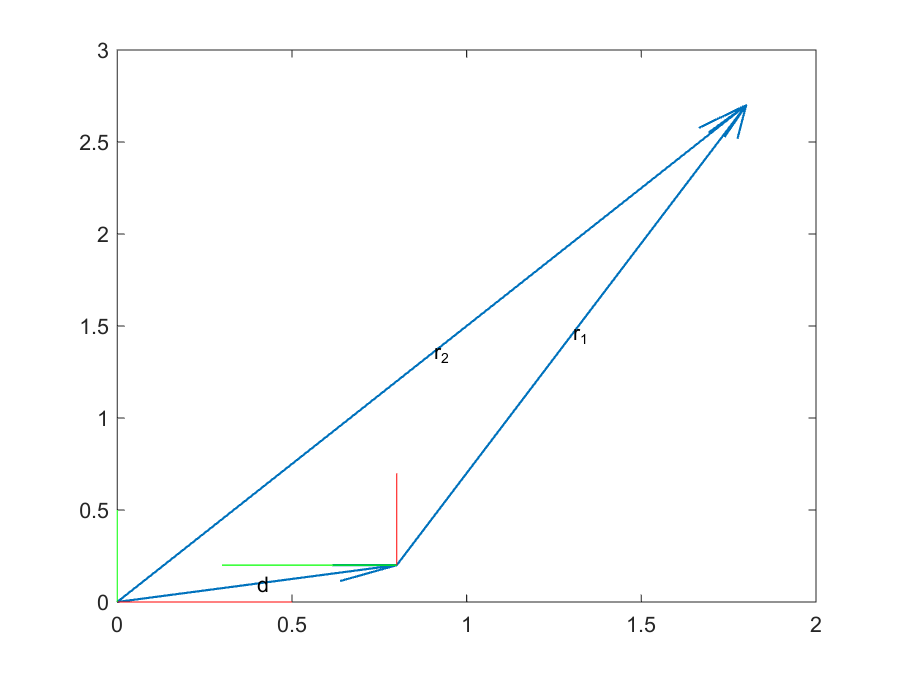

figure(3);
% Dibujo de los vectores, sin escala y grosor de dibujo 1
quiver(X,Y,U,V, 'off','LineWidth', 1)
% Agregar texto para identificar el vector
text(r1(1)/2+d(1), r1(2)/2+d(2), 'r_1')
text(d(1)/2, d(2)/2, 'd')
text(r2(1)/2, r2(2)/2, 'r_2')
% Se mantiene la figura
%Se define una rotacion de 0 respecto al eje Z
axang = [0, 0, 1, 0];      
% Se transforma en un cuaternion
quat0 = axang2quat(axang);          %Cuaternion por sistema de referencia global
%Se define una rotacion de 90° respecto al eje Z
axang = [0, 0, 1, pi/2];      
% Se transforma en un cuaternion
quat1 = axang2quat(axang);          %Cuaternion por sistema de referencia del cuerpo 1
hold on;            %Se grafica en el 
plotTransforms([0,0,0; d(1), d(2), 0], [quat0; quat1], "FrameSize", 0.5);
hold off;
view(2);

La posicion final de un punto $P$ en un sistema de referencia$B$ (o cuerpo rígido), puede ser representada por una secuencia de rotaciones sucesivas.

Para rotaciones respecto a los ejes globales


$${}^G{\mathit{\mathbf{R}}}_B=$$

$${}{\mathit{\mathbf{R}}}_{X,\alpha \;}{}{\mathit{\mathbf{R}}}_{Y,\beta \;}{}{\mathit{\mathbf{R}}}_{Z,\gamma \;}$$


Para rotaciones generales


$${}^G{\mathit{\mathbf{R}}}_{B_n }={}^G{\mathit{\mathbf{R}}}_{B_1 }{}^{B_1 }{\mathit{\mathbf{R}}}_{B_2 }{}^{B_2 }{\mathit{\mathbf{R}}}_{B_3 }{}^{B_3 }{\mathit{\mathbf{R}}}_{B_4 }\ldotp \ldotp \ldotp {}^{B_{n-1} }{\mathit{\mathbf{R}}}_{B_n }$$


Con la relación anterior es posible rdefinir la rotación de un sistema general a uno local


$$\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\mathbf{i}\cdot \mathbf{I} & \mathbf{i}\cdot \mathbf{J}\; & \mathbf{i}\cdot \mathbf{K}\\
\;\mathbf{j}\cdot \mathbf{I} & \;\mathbf{j}\cdot \mathbf{J} & \mathbf{j}\cdot \mathbf{K}\;\\
\;\mathbf{k}\cdot \mathbf{I} & \;\mathbf{k}\cdot \mathbf{J} & \mathbf{k}\cdot \mathbf{K}
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
X\\
Y\\
Z
\end{array}\right\rbrack$$


${}^B{\mathit{\mathbf{r}}}$=${}^B{\mathit{\mathbf{R}}}_G$${}^G{\mathit{\mathbf{r}}}$

Ejercicio: que relación tiene la matriz de rotación de un sistema local a general y su rotación inversa


$${}^B{\mathit{\mathbf{R}}}_G=f\left({}^G{\mathit{\mathbf{R}}}_B\right)$$


### *Otras representaciones

#### Ángulos de Euler

 
$${}^G{\mathit{\mathbf{R}}}_B=\mathit{\mathbf{R}}\left(\varphi \;,\theta \;,\psi \right)={}^G{\mathit{\mathbf{R}}}_{B^{\prime } }\left(\mathbf{K},\varphi \right){}^{B^{\prime } }{\mathit{\mathbf{R}}}_{\textrm{B"}}\left({}^{B^{\prime } }{\mathbf{i}},\theta \;\right){}^{\textrm{B"}}{\mathit{\mathbf{R}}}_B\left({}^{\textrm{B"}}{\mathbf{k}},\psi \right)$$


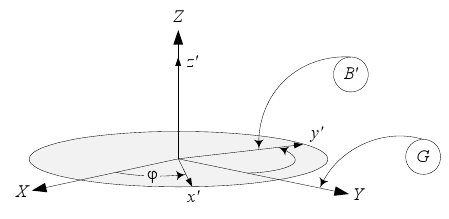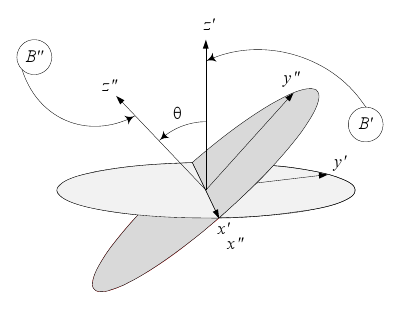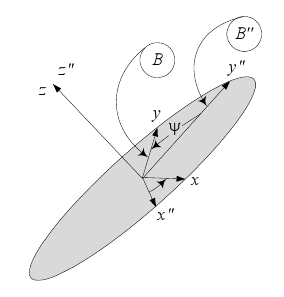

#### Eje de rotación  


$${}^G{\mathit{\mathbf{R}}}_B=\mathit{\mathbf{R}}\left(\hat{\mathit{\mathbf{u}}} ,\phi \;\right)=?$$


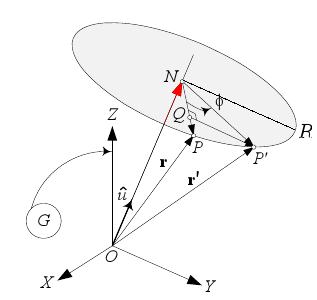$\begin{array}{l}
{\mathit{\mathbf{r}}}^{\prime } =\vec{\textrm{ON}} +\vec{{\textrm{NP}}^{\prime } } \\
\vec{\textrm{ON}} =\mathit{\mathbf{u}}\left(\mathit{\mathbf{u}}\cdot \mathit{\mathbf{r}}\right)\\
\vec{{\textrm{NP}}^{\prime } } =\cos \left(\phi \right)\vec{\textrm{NP}} +\sin \left(\phi \right)\vec{\textrm{NR}} 
\end{array}$   $\begin{array}{l}
\vec{\textrm{NP}} \cdot \;\vec{\textrm{NR}} =0\\
\vec{\textrm{NP}} =\mathit{\mathbf{r}}-\mathit{\mathbf{u}}\left(\mathit{\mathbf{u}}\cdot \mathit{\mathbf{r}}\right)\\
\vec{\textrm{NP}} =\mathit{\mathbf{u}}\times \;\left(\mathit{\mathbf{r}}-\mathit{\mathbf{u}}\left(\mathit{\mathbf{u}}\cdot \mathit{\mathbf{r}}\right)\right)=\mathit{\mathbf{u}}\times \;\mathit{\mathbf{r}}
\end{array}$ 


$$\begin{array}{l}
{\mathit{\mathbf{r}}}^{\prime } =\mathit{\mathbf{u}}\left(\mathit{\mathbf{u}}\cdot \mathit{\mathbf{r}}\right)+\cos \left(\phi \right)\left(\mathit{\mathbf{r}}-\mathit{\mathbf{u}}\left(\mathit{\mathbf{u}}\cdot \mathit{\mathbf{r}}\right)\right)+\sin \left(\phi \right)\mathit{\mathbf{u}}\times \;\mathit{\mathbf{r}}\\
{\mathit{\mathbf{r}}}^{\prime } =\left(1-\cos \left(\phi \right)\right)\mathit{\mathbf{u}}\left(\mathit{\mathbf{u}}\cdot \mathit{\mathbf{r}}\right)+\cos \left(\phi \right)\mathit{\mathbf{I}}\;\mathit{\mathbf{r}}+\sin \left(\phi \right)\mathit{\mathbf{u}}\times \;\mathit{\mathbf{r}}\\
{\mathit{\mathbf{r}}}^{\prime } =\left(\left(1-\cos \left(\phi \right)\right)\textrm{uu}+\cos \left(\phi \right)\mathit{\mathbf{I}}+\sin \left(\phi \right)\mathit{\mathbf{u}}\times \right)\;\mathit{\mathbf{r}}\\
\mathit{\mathbf{R}}\left(\mathit{\mathbf{u}},\phi \right)=\left(\left(1-\cos \left(\phi \right)\right)\textrm{uu}+\cos \left(\phi \right)\mathit{\mathbf{I}}+\sin \left(\phi \right)\mathit{\mathbf{u}}\times \right)\;
\end{array}$$


#### Cuaterniones

- Parámetros de Euler

                
$$e_{0\;} =\cos \left(\frac{\phi }{2}\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathit{\mathbf{e}}=e_1 \;\mathrm{I}+e_2 \;\mathrm{J}+e_3 \;\mathrm{K}=$$

$$\sin \left(\frac{\phi }{2}\right)\hat{u} ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;e_{0\;} ²+\mathit{\mathbf{e}}\cdot \mathit{\mathbf{e}}=1$$


- Propiedades de los cuaternoides              

               $\textrm{I²}=\textrm{J²}=\textrm{K²}=\textrm{IJK}$,            $\textrm{IJ}=-\textrm{JI}=\mathrm{K},$             $\textrm{JK}=-\textrm{KJ}=\mathrm{I}$*,*             $\textrm{KI}=-\textrm{IK}=\mathrm{J}$  

                $p+q=\left(p_0 +\mathit{\mathbf{p}}\right)+\left(q_0 +\mathit{\mathbf{q}}\right)$;      $\textrm{qp}=q_0 p_{0\;} +q_0 \mathit{\mathbf{p}}+p_{0\;} \mathit{\mathbf{q}}+\mathit{\mathbf{q}}\times \mathit{\mathbf{p}}-\mathit{\mathbf{q}}\cdot \mathit{\mathbf{p}}$;        $qq^{*\;} =q_0 ²+q_1 ²+q_2 ²+q_3 ²\;;$        $q^{-1} =\frac{q_o -\mathit{\mathbf{q}}}{qq^{*\;} }$           

- Rotación de vectores

                $p^{\prime } =\textrm{qp}q^{-1}$;            $q=q_2 q_1$

### Transformaciones Homogeneas

El movimiento de un cuerpo rígido en el espacio se compone de un moviiento de translación y rotación

 ${}^G{\mathit{\mathbf{r}}}_P$=${}^G{\mathit{\mathbf{R}}}_B$${}^B{\mathit{\mathbf{r}}}_P+{}^G{\mathit{\mathbf{d}}}_B$

 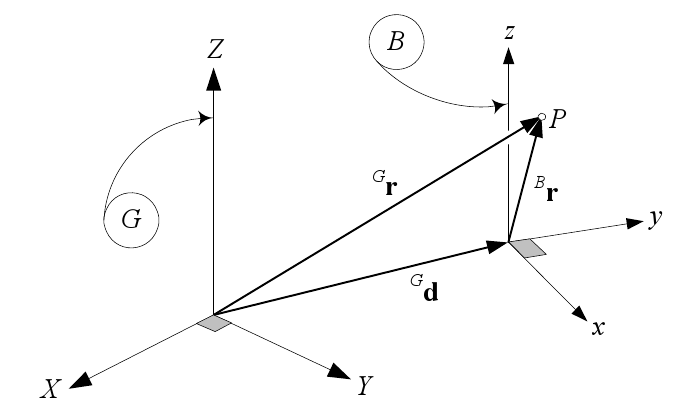

Se puede generar una matriz extendida, para representar la misma transforación de coordenadas

 ${}^G{\mathit{\mathbf{r}}}_P$=${}^G{\mathit{\mathbf{T}}}_B$${}^B{\mathit{\mathbf{r}}}_P$

 
$$\left\lbrack \begin{array}{c}
{}^G{\mathit{\mathbf{r}}}_P\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{}^G{\mathit{\mathbf{R}}}_B & {}^G{\mathit{\mathbf{d}}}_B\\
0\;\;\;0\;\;\;0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{}^B{\mathit{\mathbf{r}}}_P\\
1
\end{array}\right\rbrack$$


Ejercicio: Obtener la transformación inversa homogénea.

Por ejemplo, para un sistema con varios sistemas de referencia

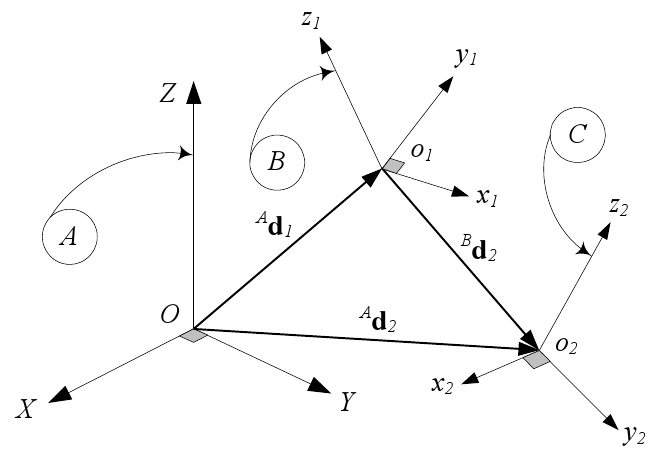

 
$${}^A{\mathit{\mathbf{T}}}_C={}^A{\mathit{\mathbf{T}}}_B{}^B{\mathit{\mathbf{T}}}_C$$


Ejercicio: Describa ${}^A{\mathit{\mathbf{T}}}_C$ en terminos de ${}^A{\mathit{\mathbf{R}}}_B$, ${}^B{\mathit{\mathbf{R}}}_C,$${}^A{\mathit{\mathbf{d}}}_1,{}^B{\mathit{\mathbf{d}}}_2$


$${}^A{\mathit{\mathbf{T}}}_C={}^A{\mathit{\mathbf{T}}}_B{}^B{\mathit{\mathbf{T}}}_C=$$

$$\left\lbrack \begin{array}{cc}
{}^A{\mathit{\mathbf{R}}}_B & {}^A{\mathit{\mathbf{d}}}_1\\
0\;\;\;0\;\;\;0 & 1
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{cc}
{}^B{\mathit{\mathbf{R}}}_C & {}^B{\mathit{\mathbf{d}}}_2\\
0\;\;\;0\;\;\;0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{}^A{\mathit{\mathbf{R}}}_B{}^B{\mathit{\mathbf{R}}}_C & {}^A{\mathit{\mathbf{R}}}_B{}^B{\mathit{\mathbf{d}}}_2+{}^A{\mathit{\mathbf{d}}}_1\\
0\;\;\;0\;\;\;0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{}^A{\mathit{\mathbf{R}}}_C & {}^A{\mathit{\mathbf{d}}}_2\\
0\;\;\;0\;\;\;0 & 1
\end{array}\right\rbrack$$


 1bclc;
clear all;

## Cinemática Directa

### Denavit Hatenberg

Un robot en articulado o en serie con $n$ articulaciones tendrá $n+1$ eslabones o cuerpos. La numeración de los enlaces comienza desde $\left(0\right)$ para el enlace base puesto a tierra inmóvil y aumenta secuencialmente hasta $\left(n\right)$ para el enlace del efector final. La numeración de las articulaciones comienza desde 1, para la articulación que conecta el primer eslabón móvil con el eslabón base, y aumenta secuencialmente hasta $n$. Por lo tanto, el eslabón $\left(i\right)$ está conectado a su eslabón inferior $\left(i-1\right)$ en su extremo proximal por la articulación $i$ y está conectado a su eslabón superior $\left(i+1\right)$ en su extremo distal por la articulación $i+1$. 

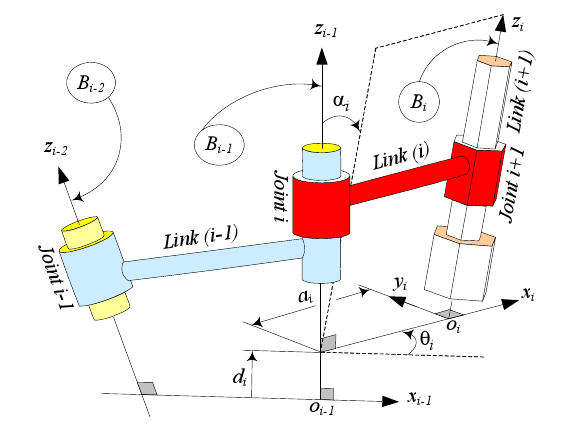

1. El eje $z_{i\;}$está alineado con el eje de articulación $i+1$.

2. El eje $x_{i\;}$ se define a lo largo de la normal común entre los ejes $z_{i-1}$ y $z_{i\;}$, apuntando desde el eje $z_{i-1}$ al eje $z_i$.  

- Cuando los dos ejes $z$ son paralelos, hay un número infinito de normales comunes. En ese caso, elegimos la normal común que escolineal con la normal común de las juntas anteriores.

- Cuando los dos ejes $z$ se intersecan, no existe una normal común entre ellos. En ese caso, asignamos el eje $x_{i\;}$ perpendicular al plano formado por los dos ejes $z$ en la dirección de $z_{i-1} \times z_i$.

- En caso de que los dos ejes $z$ sean colineales, la única disposición no trivial de las juntas es $P\parallel R$ or $R\parallel P$. Por lo tanto, asignamos el eje $x_i$ de manera que tengamos la variable conjunta igual a $\theta_{i\;}$ en la posición de reposo del robot. 

3. El eje $y_{i\;}$ está determinado por la regla de la mano derecha, $y_i =z_{i\;} \times x_{i\;}$. 

El método DH tiene 4 parámetros

1. Ángulo de giro del eslabón $\alpha_{i\;}$ es la rotación requerida del eje $z_{i-1}$ sobre el $x_i$ eje para volverse paralelo al eje $z_{i\;}$.

2. La longitud del eslabón $a_i$ es la distancia entre los ejes $z_{i-1}$ y $z_{i\;}$ a lo largo del eje  es la longitud cinemática del enlace (i).

3. El ángulo de articulación $\theta_{i\;}$ es la rotación requerida del eje $x_{i-1}$ sobre el eje $z_{i-1}$ para volverse paralelo al eje $x_i$.

4. La distancia de articulación $d_{i\;}$ es la distancia entre los ejes $x_{i-1}$ y $x_{i\;}$a lo largo del eje $z_{i-1}$. La distancia de articulación también se denomina desplazamiento de enlace.

De acuerdo con los pasos anteriores la transformación homogenea ${}^{i-1}{\mathit{\mathbf{T}}}_i=\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{k}},d_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}}{,\;\theta }_{i\;} \right)\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{i}},a_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right)$

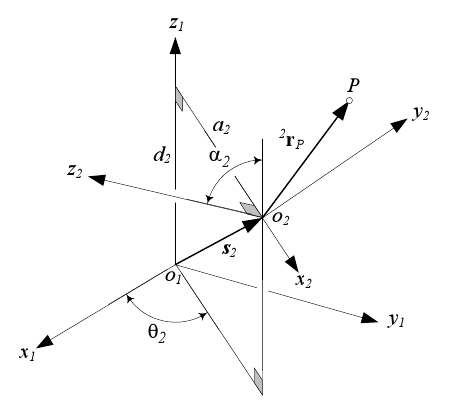


$$\begin{array}{l}
{}^{i-1}{\mathit{\mathbf{T}}}_i=\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{k}},d_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}}{,\;\theta }_{i\;} \right)\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{i}},a_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right)\\
{}^{i-1}{\mathit{\mathbf{T}}}_i=\left\lbrack \begin{array}{cc}
\mathit{\mathbf{I}} & d_{i\;} {}^{i-1}{\mathbf{k}}\\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right) & 0\;{}^{i-1}{\mathbf{k}}\\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{I}} & a_{i\;} {}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right) & 0\;{}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack \\
{}^{i-1}{\mathit{\mathbf{T}}}_i=\left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right) & d_{i\;} \;{\mathbf{k}}_{i-1} \\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right) & a_i \;{}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack \\
{}^{i-1}{\mathit{\mathbf{T}}}_i=\left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right) & d_{i\;} \;{\mathbf{k}}_{i-1} +\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right)a_i \;{}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack 
\end{array}$$


### Construcción de robot

clc;
clear all;

Para el cuerpo 1 y su junta con la base.

%Declarar eslabon1
body1 = rigidBody('body1') 
%Declarar una junta/articulacion1 entre la base y el eslabon1 
jnt1 = rigidBodyJoint('jnt1','revolute')
jnt1.HomePosition = pi/3               %Posicion inicial de la junta
tform = trvec2tform([0.25, 0.25, 0])    %Transformación homogenea de un vector de traslacion 3D
setFixedTransform(jnt1,tform)          %Se adjunta la transformacion homogenea a la junta
body1.Joint = jnt1                     %Se agrega al eslabon1 la junta 1

Construccion de la cadena cinemática

robot = rigidBodyTree           %la cadena cinemática se contiene en una estructura rigidBodyTree
addBody(robot,body1,'base')     %Agrega eslabon1 a la base, mediante junta1 

Desplegar resultados actuales

showdetails(robot)              %Despliega los actuales elementos dentro de la cadena cinematica
figure(1);          %Muestra sistemas coordenados
show(robot);        %Muestra el robot dentro de un espacio 3D
view(2)             %Restringimos la vista a 2D

Agregar un segundo cuerpo

body2 = rigidBody('body2');                     %Declaración de eslabon2
jnt2 = rigidBodyJoint('jnt2','revolute');       %Junta entre eslabon1 y eslabon2, junta2
jnt2.HomePosition = pi/2;                       %Posición original
tform2 = trvec2tform([1, 0, 0]);                %Vector de traslación definido en transformación homogenea
setFixedTransform(jnt2,tform2);                 %Se adjunta la transformación a la junta2
body2.Joint = jnt2;                             %Se agrega la junta al cuerpo
addBody(robot,body2,'body1');                   %Se agrega el cuerpo2 al cuerpo1 mediante la junta2

Desplegar resultados

showdetails(robot)      %Despliega los actuales elementos dentro de la cadena cinematica
figure(2);              %Muestra sistemas coordenados
show(robot);            %Muestra el robot dentro de un espacio 3D
view(2) 

### Construcción mediante parametros DH

clc;
clear all;
dhparams = [0.25*sqrt(2), 0, 0, pi/6;
            1,            0, 0, pi/2]
robot = rigidBodyTree;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;
addBody(robot,body1,'base')
jnt1.ChildToJointTransform
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,dhparams(2,:),'dh');
body2.Joint = jnt2;
addBody(robot,body2,'body1')
jnt2.ChildToJointTransform
showdetails(robot)      %Despliega los actuales elementos dentro de la cadena cinematica
figure(2);              %Muestra sistemas coordenados
show(robot);            %Muestra el robot dentro de un espacio 3D
view(2) 

### Configuración de Eslabones con Parámetros DH

clc;
clear all;
syms a_i d_i theta_i alpha_i t l     % Parámetros DH
I4= sym(eye(4));                    % Transformación homogenea general
Rx = I4;                            % Transformación homogenea de rotacion sobre eje X
Rx(1:3,1:3) = [1 0 0; 0 cos(t) -sin(t); 0 sin(t) cos(t)];       
Rx = subs(Rx, t, alpha_i)
Dx = I4;                    % Transformación homogenea de desplazamiento sobre eje X
Dx(1:3,4) = [a_i; 0; 0]
Rz = I4;                    % Transformación homogenea de rotacion sobre eje Z
Rz(1:3,1:3) = [cos(t) -sin(t) 0; sin(t) cos(t) 0; 0 0 1];
Rz = subs(Rz, t, theta_i)
Dz = I4;                    % Transformación homogenea de desplazamiento sobre eje Z
Dz(1:3,4) = [0; 0; d_i]
Ti_j = Dz*Rz*Dx*Rx

Proximal R y distal paralelo R o P, $R\parallel R\left(\alpha_{i\;} =0,\pi \right)$ o $R\parallel P\left(\alpha_{i\;} =0\right)$

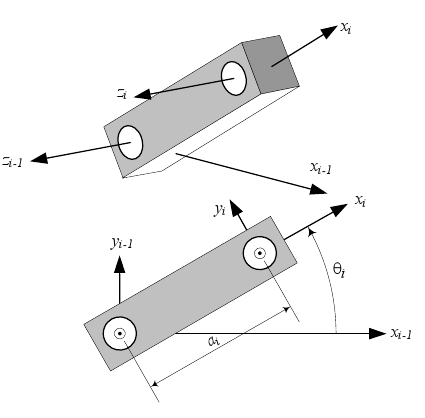

subs(Ti_j,[alpha_i, theta_i, d_i],[0, theta_i, d_i])

Proximal R y distal perpendicular R o P, $R\bot R\left(\alpha_{i\;} =\frac{\pi }{2}\right)$ o $R\bot P\left(\alpha_{i\;} =\frac{\pi }{2}\right)$

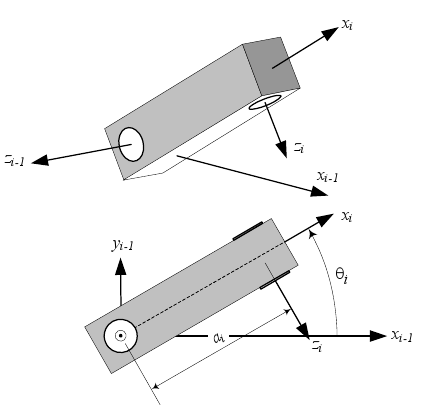

subs(Ti_j,[alpha_i, theta_i, d_i],[pi/2, theta_i, d_i])

Proximal R y distal ortogonal R o P, $R\vdash R\left(\alpha_{i\;} =\pm \frac{\pi }{2},a_{i\;} =0\right)$ o $\pm \left(\alpha_{i\;} =\frac{\pi }{2},a_{i\;} =0\right)$

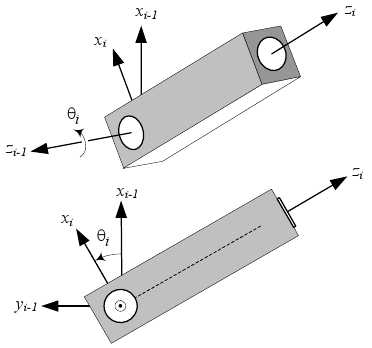

subs(Ti_j,[alpha_i, a_i, theta_i, d_i], [pi/2, 0, theta_i, d_i])

Proximal P y distal paralelo R o P, $P\parallel R\left(\alpha_{i\;} =0,\theta_{i\;} =0\right)$ o $R\parallel P\left(\alpha_{i\;} =0,\theta_{i\;} =0\right)$

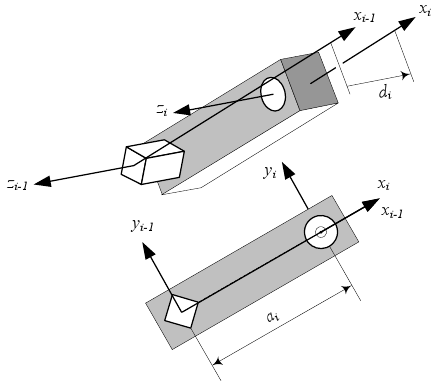

subs(Ti_j,[alpha_i, theta_i, d_i],[0, theta_i, d_i])

Proximal P y distal perpendicular R o P, $P\bot R\left(\alpha_{i\;} =\frac{\pi }{2},\theta_{i\;} =0\right)$ o $P\bot P\left(\alpha_{i\;} =\frac{\pi }{2},\theta_{i\;} =0\right)$

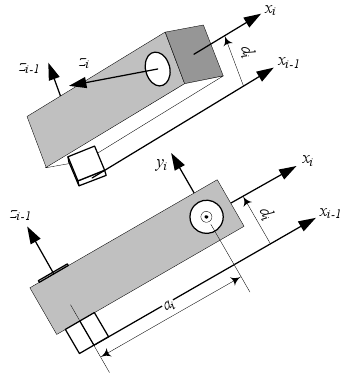

subs(Ti_j,[alpha_i, theta_i, d_i],[pi/2, theta_i, d_i])

Proximal P y distal ortogonal R o P,  $R\vdash R\left(\alpha_{i\;} =\frac{\pi }{2},a_{i\;} =0,\theta_i =0\right)$ o $R\vdash P\left(\alpha_{i\;} =\frac{\pi }{2},a_{i\;} =0,\theta_i =0\right)$

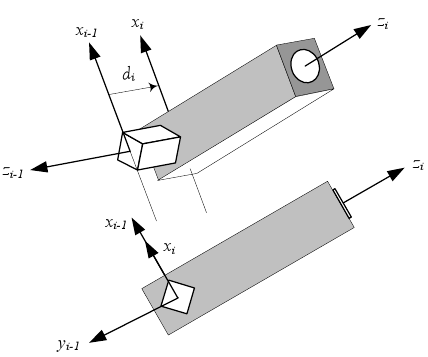

subs(Ti_j,[alpha_i, theta_i, a_i, d_i],[pi/2, 0, 0, d_i])

### Ejemplo: PUMA' = $R\vdash R\parallel R$$\vdash R$

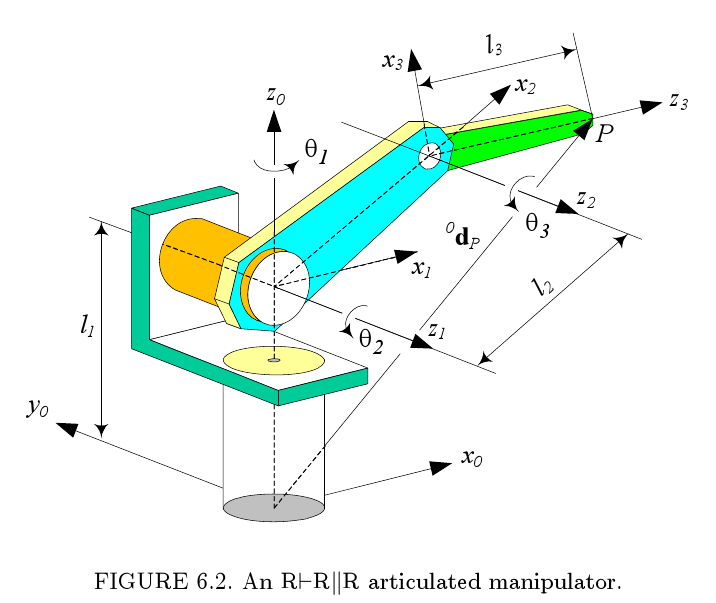


$$\left\lbrack \begin{array}{ccccc}
i & a_{i\;}  & \alpha_i  & d_i  & \theta_i \\
0\to 1 & 0 & \frac{\pi }{2} & l_1  & \theta_1 \\
1\to 2 & l_2  & 0 & 0 & \theta_2 \\
2\to 3 & 0 & \frac{\pi }{2} & 0 & \theta_3 
\end{array}\right\rbrack$$


Variables y parámetros para el robot PUMA'

syms l_1 l_2 l_3 theta_1 theta_2 theta_3
T0_1 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[0, pi/2, l_1, theta_1])      % Transformacion Homogenea 0->1
T1_2 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[l_2, 0, 0, theta_2])         % Transformacion Homogenea 1->2
T2_3 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[0, pi/2, 0, theta_3])        % Transformacion Homogenea 2->3
T0_3 =(T0_1*T1_2*T2_3)          % Transformacion Homogenea 0->3
T0_3 = simplify(T0_3)

La matriz columna del punto del efector final representado en el sistema 3, se representa como la distancia del último brazo

d3_p = [0; 0; l_3; 1]       % Vector de efector final p en 3

Es posible expresar esa matriz en sistema 0 (el sistema de referencia).

d0_p = T0_3*d3_p            % Vector de efector final p en 0

El objetivo de la cinemática inversa es obtener las variables de las juntas cinemáticas en función de la posición final del efector $\theta_1 \left(d_x ,d_y ,d_z \right),\theta_2 \left(d_x ,d_y ,d_z \right),\theta_3 \left(d_x ,d_y ,d_z \right)\;$

syms d_x d_y d_z
% equ(1) = d_x == d0_p(1);
% equ(2) = d_y == d0_p(2);
% equ(3) = d_z == d0_p(3);
% sol = solve(equ,[theta_1, theta_2, theta_3])

### Cinemática Inversa

### Método de desacoplamiento:

Para este robot en específico, con juntas cinemáticas rotacionales, podemos arreglar los términos de la matriz ${}^0{\mathit{\mathbf{d}}}_p$ para obtener una relación trigonometrica $a\;\sin \left(\theta \right)+b\;\cos \left(\theta \right)=c$

syms a b c
equ0 = a*cos(theta_i) + b*sin(theta_i) - c == 0;
sol0 = solve(equ0, [theta_i])
equT = [d_x; d_y; d_z; 1] == d0_p

Para el giro $\theta_1$, se puede manipular $d_x$ y $d_y$, obtener la relación $a\;\sin \left(\theta \right)+b\;\cos \left(\theta \right)=c$

equ1 = equT(1)*sin(theta_1) - equT(2)*cos(theta_1)
equ1 = (lhs(equ1)) == simplify(rhs(equ1))
sol1 = coeffs(lhs(equ1), [cos(theta_1), sin(theta_1)])

Por tanto

t1 = subs(sol0, [a, b, c], [sol1(1), sol1(2), 0])

Para el ángulo $\theta_2$, lo que se busca es tener eliminar los terminos que contengan $\theta_3$

equ2 = equT(1)*cos(theta_1) + equT(2)*sin(theta_1)
equ2 = (lhs(equ2)) == simplify(rhs(equ2))
equ2 = equ2 - l_2*cos(theta_2)
equ3 = (equT(3) - l_1 - l_2*sin(theta_2))*(-1)

Si equ2 y equ3 los elevamos al cuadrado y sumamos, obtenemos una ecuación sin terminos en $\theta_3$

equ4 = simplify(equ2^2+equ3^2)
equ4 = simplify((expand(equ4)))
equ4 = collect(equ4 - rhs(equ4),[cos(theta_2), sin(theta_2)])
sol2 = coeffs(lhs(equ4), [cos(theta_2), sin(theta_2)])
t1 = subs(sol0, [c, b, a], [-sol2(1), sol2(2), sol2(3)])

Dado que ya tenemos $\theta_1$ y $\theta_2$, podemos obtener $\theta_3$, dividiendo equ2 y equ3

equ5 = (equ2/equ3)

### Método de numérico:


$$\left\lbrack \begin{array}{ccccc}
i & a_{i\;}  & \alpha_i  & d_i  & \theta_i \\
0\to 1 & 0 & \frac{\pi }{2} & l_1  & \theta_1 \\
1\to 2 & l_2  & 0 & 0 & \theta_2 \\
2\to 3 & 0 & \frac{\pi }{2} & 0 & \theta_3 
\end{array}\right\rbrack$$


clc;
clear all;


Distancias de los eslabones

l_1 = 0.3;      l_2 = 0.4;          l_3 = 0.3;


Parametros DH $a_i ,{\;\alpha }_i ,d_i ,\theta_i$

dhparams = [0,   pi/2,     l_1,      0;
            l_2,   0,       0,       0;
            0,   pi/2,      0,       0;
            0,     0,       l_3,     0];  


Estructura de datos para junta cinemática

cougar = rigidBodyTree;


Estruturas para cuerpos y juntas

cuerpo = {'base', 'tronco', 'brazo', 'a-brazo', 'muñon'};
    junta = {'cintura', 'hombro', 'codo', 'muñeca'};
tipoJunta = {'revolute', 'revolute', 'revolute', 'fixed'};



Construccion del robot

for i = 1:length(junta)
    body(i) = rigidBody(cuerpo{i+1});
    jnt(i) = rigidBodyJoint(junta{i}, tipoJunta{i});
    setFixedTransform(jnt(i),dhparams(i,:),'dh');
    body(i).Joint = jnt(i);
    addBody(cougar,body(i),cuerpo{i})
    jnt(i).ChildToJointTransform
end

Despliega los resultados de la cadena cinemática

showdetails(cougar)

Definir la trayectoria a seguir por el muñon

t = (0:0.2:10)';        % Tiempo
N_t = length(t);        % Numero de elementos de la matriz tiempo
c = [0.2 0.3 0];          % Centro del circulo
r = 0.2;                % Radio del cirulo
theta = t*(2*pi/t(end));        % 'Angulo de avance en el circulo
p = c + r*[cos(theta) sin(theta) zeros(size(theta))];       % El famoso punto p

Configuración del robot, es decir, los valores que toma cada una de las variables de las juntas $q=\left\lbrack \begin{array}{cccc}
\theta_1 \left(t\right) & \theta_2 \left(t\right) & \ldotp \ldotp \ldotp  & \theta_n \left(t\right)
\end{array}\right\rbrack$

q0 = homeConfiguration(cougar);     % Configuración inicial 
ndof = length(q0);                  % Grados de libertad

Solucionador para cinemática inversa

ik = inverseKinematics('RigidBodyTree', cougar);        %Recibe como argumentos el tipo de objeto y el objeto, en este caso una cadena cinematica
VecPesos = [0, 0, 0, 1, 1, 1];     % Valores entre 0-1, son las tolerancias de la pose, 3 para orientación y 3 para posición
Effector = 'muñon';                % Cuerpo donde se miden las transformaciones del punto final

Iterador

q{1} = q0;              % Condiciones iniciles, configuracion inicial
for i = 1:N_t
    q{i+1} = ik(Effector, trvec2tform(p(i,:)), VecPesos, q{i});  % Se obtiene la nueva configuración q{i+1}, utilizando la configuración anterior q{i}
    tF = getTransform(cougar, q{i+1}, Effector);
    for j = 1:ndof      % Se obtienen los valores de las juntas y las posiciones del efector para graficarlas
        theta(i,j) = q{i}(j).JointPosition; 
        Pnt(i,j) = tF(j,4);
    end
end

Dibujos

% close all;
figure(1)                                           
plot3(Pnt(:,1), Pnt(:,2), Pnt(:,3), 'r');               % Grafica los puntos del efector en rojo
hold on
plot3(p(:,1), p(:,2), p(:,3),'k');                      % Grafica los puntos de la trayectoria en negro
axis([ -0.0257    0.5018   -0.1640    0.2610   -0.2145    0.5480])

% keyboard;
for i = 1:N_t
    show(cougar, q{i+1}, 'PreservePlot', false);        % Despliga la configuracion del robot para cada punto de la trayectoria
    drawnow
    waitfor(rateControl(20));
end
show(cougar, q{i+1}, 'PreservePlot', true);        

hold off
figure(2)
plot(t, theta(:,1), t, theta(:,2), t, theta(:,3), 'lineWidth', 2);      % Grafica los valores del juntas cinematicas en funcion del tiempo
legend('\theta_1', '\theta_2', '\theta_3');
% axis tight
